clear;
load("path_1.mat");
load("path_2.mat");
load("path_3.mat");
load("path_4.mat");
load("path_5.mat");
load("path_6.mat");

path = path_2;
v = 15;
start_x = path(1, 2);
start_y = path(1, 3);
room_x = 25;
room_y = 25;
resolution = 50; % Liczba punktów między dwoma pozycjami
tau = 0.01;  % stała czasowa
global T
T = 10; % czas trwania symulacji

global P I D
P = 1;
I = 0;
D = 0;

m = 10;  % kg
R = 0.1;  % m
g = 9.81;  % m/s
N_max = 10;  % Nm

Ścieżki bez przeszkód

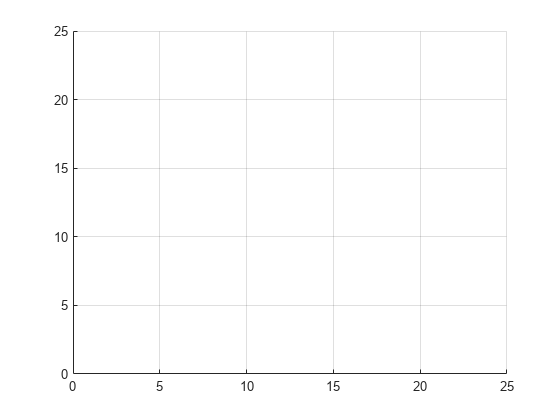

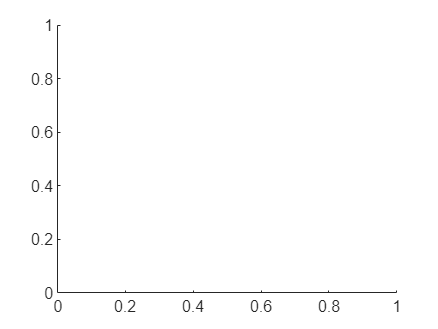

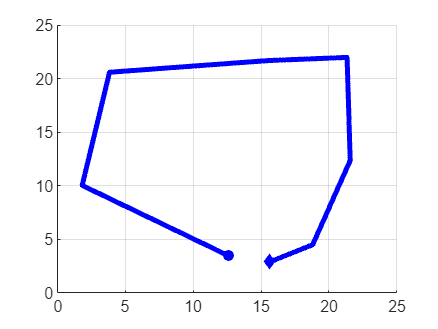

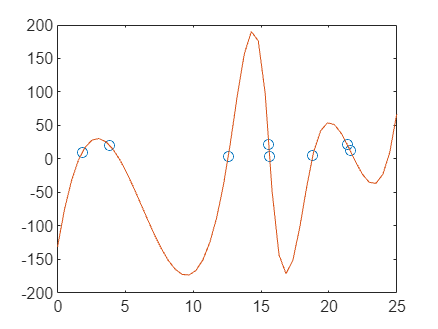

%path_1 = get_path(room_x, room_y, resolution, []);

%path_2 = get_path(room_x, room_y, resolution, []);
%path_3 = get_path(room_x, room_y, resolution, []);

%save('path_1.mat','path_1')
%save('path_2.mat','path_2')
%save('path_3.mat','path_3')

Ścieżki z przeszkodami

%obstacles = get_obstacles(room_x, room_y);
%path_4 = get_path(room_x, room_y, resolution, obstacles);
%path_5 = get_path(room_x, room_y, resolution, obstacles);
%path_6 = get_path(room_x, room_y, resolution, obstacles);

%save('path_4.mat','path_4')
%save('path_5.mat','path_5')
%save('path_6.mat','path_6')

close all;

options = optimset('TolFun', 0.01, 'TolX', 0.01, 'MaxFunEvals', 10);
%[best_x, error] = fminsearch(@ident_error, [P, I], options)
[best_x, error] = fmincon(@ident_error, [P], [], [], [], [], [0 0 0], [], [], options)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


best_x = 0.0044

error = 2.7412e+03

function error = ident_error(x)
    global P I D T

    P = x(1);
    %I = x(2);
    %D = x(3);
    
    sim_out = sim("zad2.slx", T);
    
    error = double(sim_out.error.signals.values(end));
end

function obstacles = get_obstacles(room_x, room_y)
    figure; hold on;
    axis([0 room_x 0 room_y]);
    grid on;
    no_obst = inputdlg("Podaj liczbę przeszkód");
    no_obst = str2double(no_obst{1});
    obstacles = {};
    i = 0;
    while i < no_obst
        n = inputdlg("Podaj liczbę kątów przeszkody");
        n = str2double(n{1});
        while n < 3
            n = inputdlg("Podaj liczbę kątów przeszkody");
            n = str2double(n{1});
        end

        new_obstacle = [];
        [x, y] = ginput(1);
        new_obstacle = [new_obstacle; x, y];
        plot(x, y, "r*");
        j = 0;
        while j < n - 1
            try
                [x, y] = ginput(1);  
            catch
                break;
            end
        
            if (~isempty(x)) & (~isempty(y))
                new_obstacle = [new_obstacle; x, y];
                plot(x, y, "r*");
                line([new_obstacle(end - 1, 1), new_obstacle(end, 1)], [new_obstacle(end - 1, 2), new_obstacle(end, 2)], "Color", "r")
            end
            j = j + 1;
        end

        obstacles = [obstacles new_obstacle];

        i = i + 1;
    end
    
    hold off;
end

function path = get_path(room_x, room_y, resolution, obstacles)
    global T

    figure; hold on;
    if ~isempty(obstacles)
        for i = 1 : length(obstacles)
            obst = obstacles{i};
            patch(obst(:, 1), obst(:, 2), "red")
        end
    end
    axis([0 room_x 0 room_y]);
    grid on;
    
    track_pos = [];
    [x, y] = ginput(1);
    track_pos = [track_pos; x, y];
    plot(x, y, "r*");
    while true
        try
            [x, y] = ginput(1);  
        catch
            break;
        end
    
        if (~isempty(x)) & (~isempty(y))
            track_pos = [track_pos; x, y];
            plot(x, y, "r*");
            line([track_pos(end - 1, 1), track_pos(end, 1)], [track_pos(end - 1, 2), track_pos(end, 2)], "Color", "r")
        end
    end
    
    hold off;
    
    %x = track_pos(:,1);
    %y = track_pos(:,2);
    %t = linspace(0, room_x, resolution);
    %curve_track = interp1(x, y, t, 'spline');
    %figure;
    %plot(x, y, 'o', t, curve_track);

    robot_track = [];
    for i = 1 : length(track_pos) - 1
       new_section = [linspace(track_pos(i, 1), track_pos(i + 1, 1), resolution); linspace(track_pos(i, 2), track_pos(i + 1, 2), resolution)];
       robot_track = [robot_track new_section];
    end
    
    figure; hold on;
    plot(robot_track(1, 1), robot_track(2, 1), 'bo', "MarkerFaceColor", "b")
    plot(robot_track(1, :), robot_track(2, :), 'b', "LineWidth", 3);
    plot(robot_track(1, end), robot_track(2, end), 'bdiamond', "MarkerFaceColor", "b")
    axis([0 room_x 0 room_y]);
    if ~isempty(obstacles)
        for i = 1 : length(obstacles)
            obst = obstacles{i};
            patch(obst(:, 1), obst(:, 2), "red")
        end
    end
    grid on; hold off

    t = linspace(0, T, length(robot_track));
    path = [t; robot_track(1, :); robot_track(2, :)]';
end